Set up the code to plot logistic growth of an *E. coli* colony over time.

N(t) = N(t-1) + (dN/dt)dt

Time(1)=0;
N(1)=1; %start with 1 cell
r=1/20; %in 1/min
dt=0.1; %in minutes
Nsteps=1000;
K=1000; %in cells

for i=2:Nsteps
    N(i)=N(i-1)+(r*N(i-1)*dt);
    r=r*(1-((N(i-1)/K)));
    Time(i)=Time(i-1)+dt;
end

Plot the results.

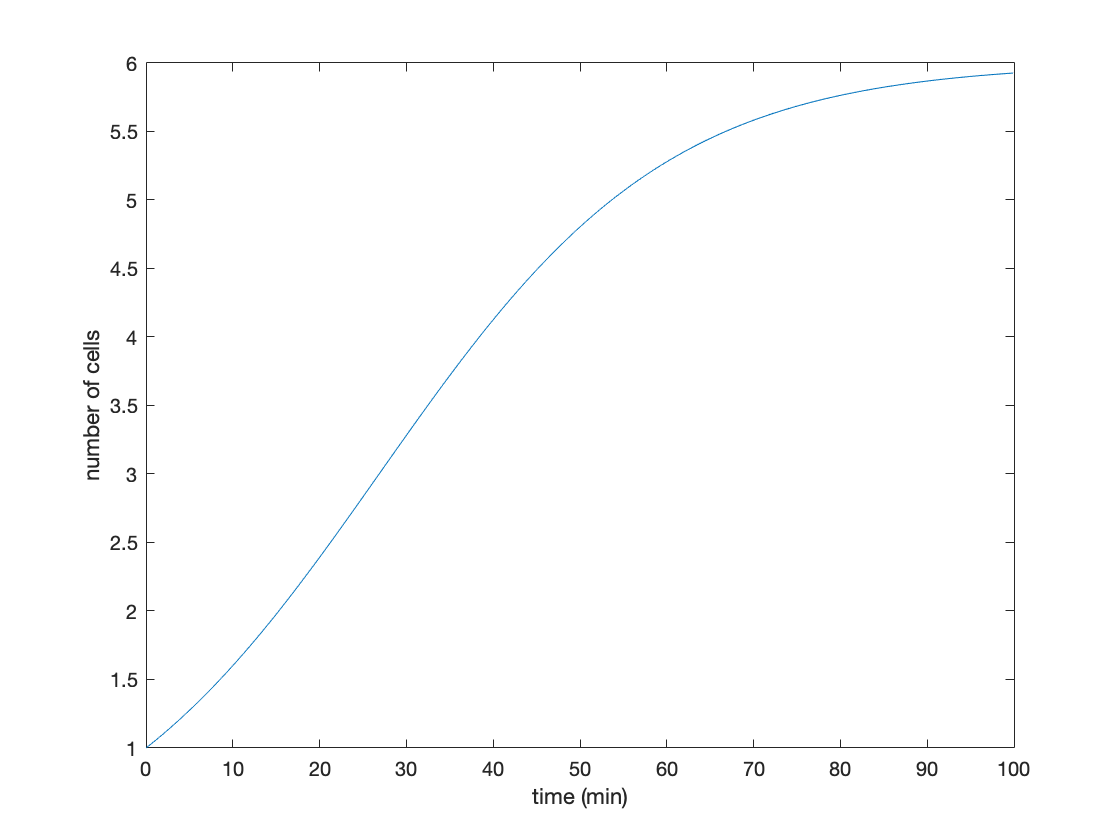

plot(Time, N)
xlabel('time (min)')
ylabel('number of cells')